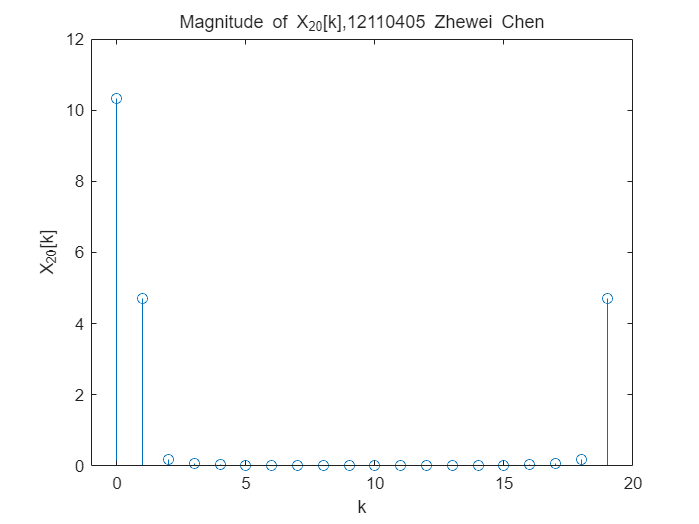

clc,clear,close all;
x=hamming(20);
X=DFTsum(x);
k=0:19;
figure
stem(k,abs(X));
xlabel('k');
ylabel('X_{20}[k]');title('Magnitude of X_{20}[k],12110405 Zhewei Chen');xlim([-1,20])

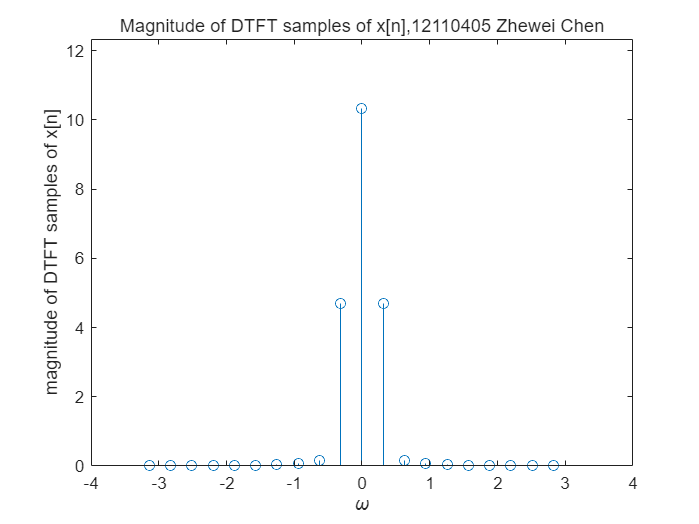

figure
[X1,w1] = DTFTsamples(x);
stem(w1, abs(X1) ) ,xlabel ( '\omega') ,ylabel ('magnitude of DTFT samples of x[n]') 
xlim ([-4,4]) ; ylim([0,max(abs(X1))+2]) ;
title('Magnitude of DTFT samples of x[n],12110405 Zhewei Chen')

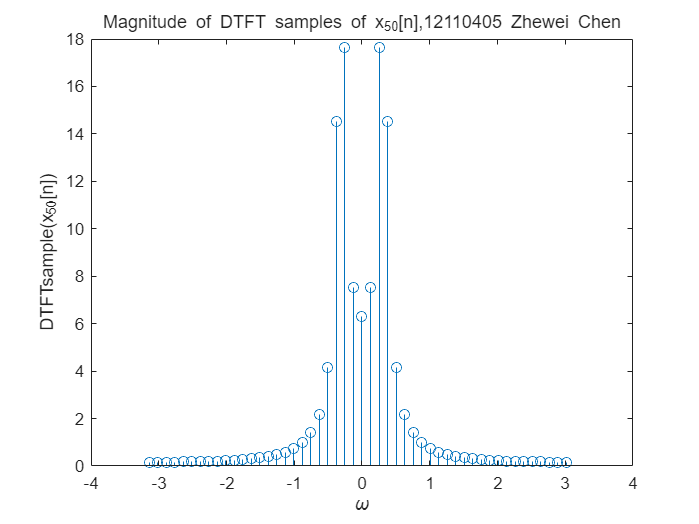

clc,clear;
n1=0:49;
x1=sin(0.1*pi*n1);
[X1,w1]=DTFTsamples(x1);

stem(w1,abs(X1));xlabel('\omega'),ylabel('DTFTsample(x_{50}[n])'),title('Magnitude of DTFT samples of x_{50}[n],12110405 Zhewei Chen');

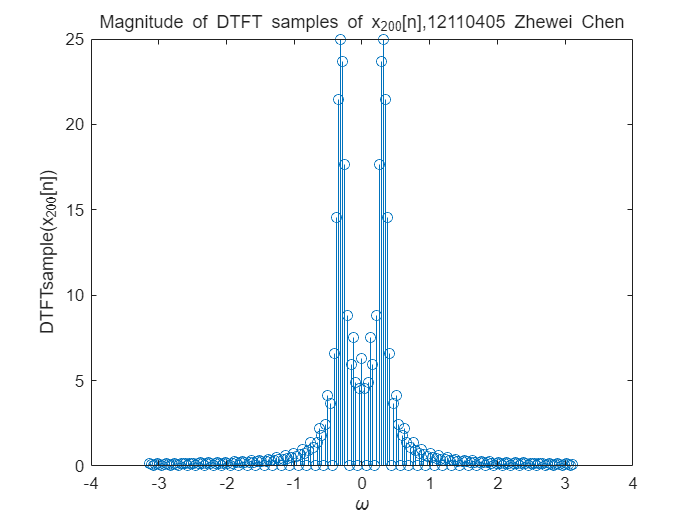

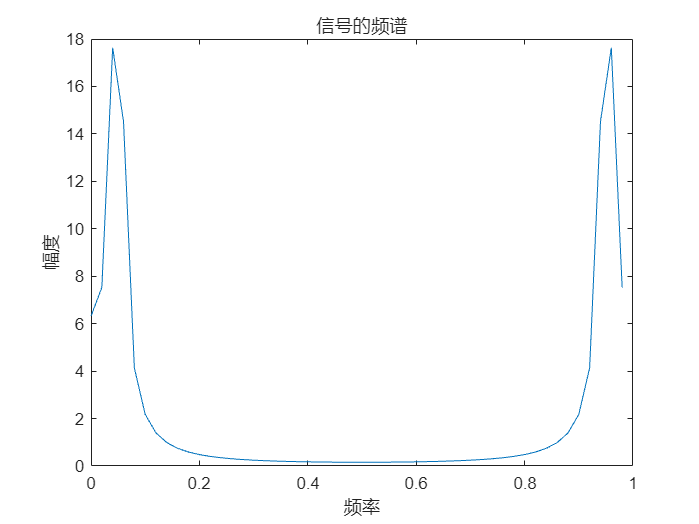

n2=0:199;
x2=(n2<=49).*sin(0.1*pi*n2);
[X2,w2]=DTFTsamples(x2);
figure
stem(w2,abs(X2));xlabel('\omega'),ylabel('DTFTsample(x_{200}[n])'),title('Magnitude of DTFT samples of x_{200}[n],12110405 Zhewei Chen');